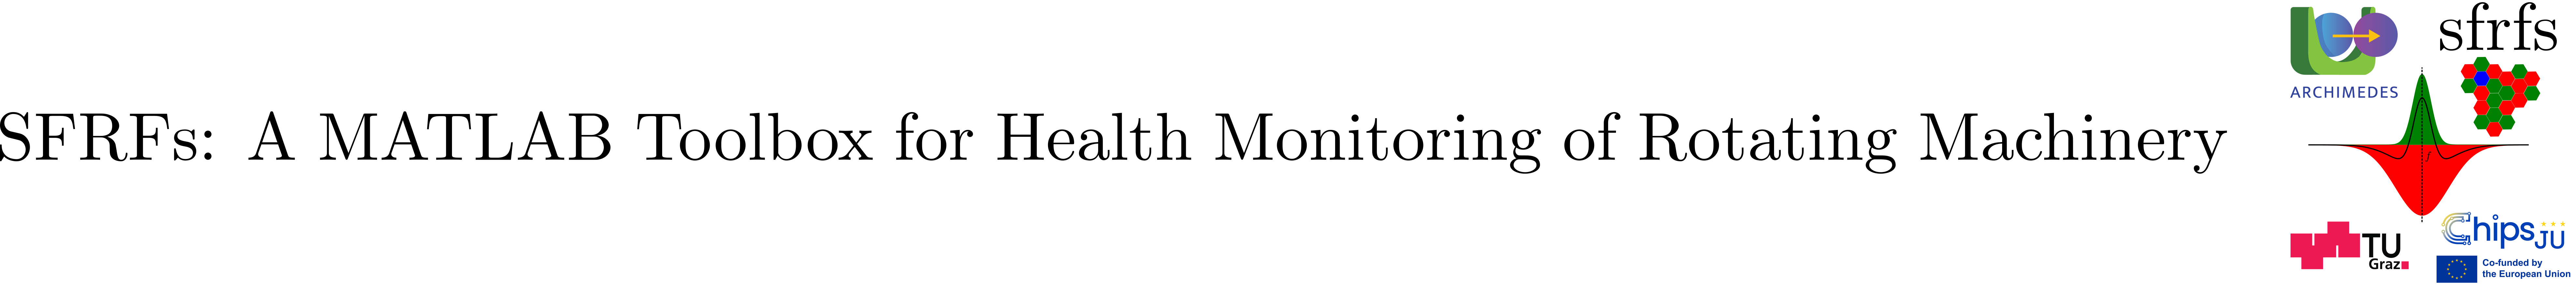

# ReceptiveFieldResponseFunctions

## Summary

ReceptiveFieldResponseFunctions provides factory methods for constructing receptive field response functions (RFRFs) that map masked spectra to scalar response values.

## Description

ReceptiveFieldResponseFunctions defines a collection of static factory methods that return response functions operating on masked spectra and their associated frequency axes. Each factory produces a function handle that maps a spectrum segment to a scalar response per snapshot or column.

The provided response functions implement integral-based and information-theoretic readouts over receptive-field masks, including absolute integral measures, frequency-scaled integrals, and entropy-based measures. These operators are used downstream of receptive-field gain masks and upstream of contrast mappings.

All response functions share a common call signature and are designed to be injected into center-surround and gain-function processing pipelines.

### Public methods

#### integralAbs

Construct an absolute-magnitude integral response function.

**Syntax (by example)**

- `rf = ReceptiveFieldResponseFunctions.integralAbs();`

Computes the numerical (trapezoidal rule) integral of the magnitude spectrum over the frequency axis.

#### **integralAbsFreqScaled**

Construct a frequency-scaled absolute integral response function.

**Syntax (by example)**

- `rf = ReceptiveFieldResponseFunctions.integralAbsFreqScaled( ...`

`        order = p, ...`

`        freqFloorHz = f0);`

Applies frequency weighting of order `p` prior to integration, with a low-frequency floor for numerical stability.

#### velocityLike

- Construct a first-order frequency-scaled integral response function.

- Equivalent to `integralAbsFreqScaled(order = 1, ...)`.

#### displacementLike

- Construct a second-order frequency-scaled integral response function.

- Equivalent to `integralAbsFreqScaled(order = 2, ...)`.

#### entropy

Construct an entropy-based response function over normalized magnitudes.

**Syntax (by example)**

- `rf = ReceptiveFieldResponseFunctions.entropy( ...`

`        normalize = ``true``, ...    `

`        eps`` = ``1e-12``);`

Computes spectral entropy over magnitude-derived weights with numerical regularization. Optional normalization scales entropy relative to the maximum entropy for the bin count.

**Response function families**

The class currently provides three response families:

- **Absolute integral responses**Magnitude-based trapezoidal integrals over masked spectra.

- **Frequency-scaled integral responses**Integral responses with power-law frequency weighting, enabling velocity-like and displacement-like regimes.

- **Entropy responses**Dispersion-based measures over normalized magnitude weights within a mask.

All families return one scalar response per spectrum column (i.e., a row vector across snapshots).

#### Common call contract

All returned response functions follow the same interface:

- `y = rf(Xmask, f)`

**Inputs**

- `Xmask` — masked spectrum matrix (frequency bins × snapshots)

- `f` — frequency axis vector (Hz)

**Output**

- `y` — row vector of scalar responses (one per snapshot/column)

Validation ensures dimensional consistency and a finite, real frequency axis.

## Example

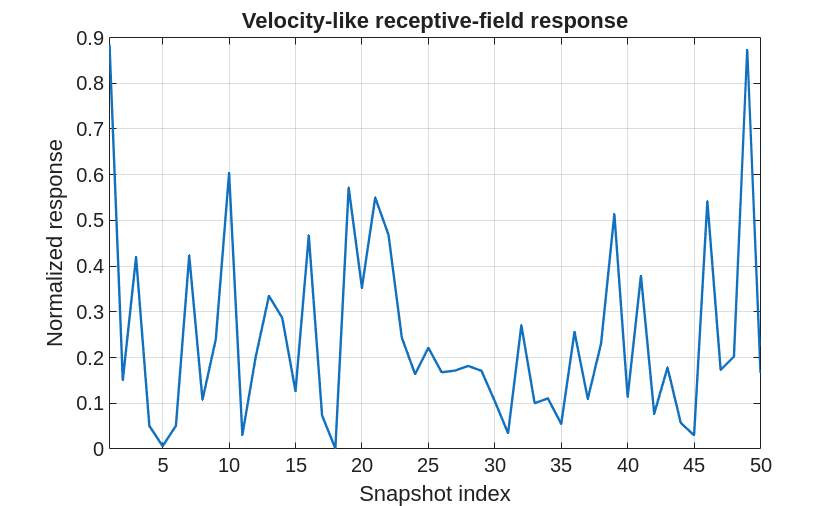

% Frequency axis
f = linspace(0, 200, 1024).';

% Synthetic spectra
nSnapshots = 150;
memberTable = buildSyntheticMemberTable(f, nSnapshots);

% Stack spectra into matrix (bins x snapshots)
X = zeros(numel(f), nSnapshots);
for i = 1:nSnapshots
    X(:, i) = memberTable.FFT{i};
end

% Velocity-like response (order = 1)
rf = ReceptiveFieldResponseFunctions.velocityLike( ...
    freqFloorHz = 1e-3);

y = rf(X, f);

% Display helper
plotNormalizedResponse(y, "Velocity-like receptive-field response");

## API documentation

### MATLAB help

help ReceptiveFieldResponseFunctions

  ReceptiveFieldResponseFunctions  A standard library with common receptive
  field response functions (RFRFs)
 
  Static factory methods returning function handles with signature:
    r = fcn(X, f)
  where:
    X is a (real or complex) spectrum matrix [nBins x nSnapshots]
    f is a frequency axis vector            [nBins x 1] (or [1 x nBins])
 
  The returned r contains one scalar response per snapshot/column.

    Documentation for ReceptiveFieldResponseFunctions



## Source code

The source of the class can be found in [ReceptiveFieldResponseFunctions](matlab:open('../../ReceptiveFieldResponseFunctions.m')).

## Test

A unit test for validations performed by the static method in this class can be found in [TestReceptiveFieldResponseFunctions](matlab:open('../../../tests/TestReceptiveFieldResponseFunctions.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestReceptiveFieldResponseFunctions');

Running TestReceptiveFieldResponseFunctions
..........
Done TestReceptiveFieldResponseFunctions
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestReceptiveFieldResponseFunctions/testIntegralAbsMatchesTrapz                  | Passed
TestReceptiveFieldResponseFunctions/testEntropyNormalizedUniformIsOne            | Passed
TestReceptiveFieldResponseFunctions/testEntropyUnnormalizedUniformIsLogNBins     | Passed
TestReceptiveFieldResponseFunctions/testIntegralAbsFreqScaledOrderZeroEqualsI... | Passed
TestReceptiveFieldResponseFunctions/testVelocityLikeEqualsOrder1                 | Passed
TestReceptiveFieldResponseFunctions/testDisplacementLikeEqualsOrder2             | Passed
TestReceptiveFieldResponseFunctions/testValidateXFMismatchThrows                 | Passed
TestReceptiveFieldResponseFunctions/testInvalidSpectrumThrows                    | Passed
TestReceptiveFieldResponseFunctions/testInvalidFreqAxisThrows                    | Passed
TestRecept

## Auxiliary functions

### Plot RFRFs

function plotNormalizedResponse(y, plotTitle)
% plotNormalizedResponse Plot a normalized response vector.
%
% plotNormalizedResponse(y, plotTitle) scales y to [0,1] and plots it
% versus snapshot index for visualization.
    y = y(:);
    y = y - min(y);
    if max(y) > 0
        y = y ./ max(y);
    end
    
    figure;
    plot(y, "LineWidth", 1.2);
    grid on;
    xlabel("Snapshot index");
    ylabel("Normalized response");
    title(plotTitle, "Interpreter","none");
    xlim([1 50]);
end

### Synthetic member table construction

function memberTable = buildSyntheticMemberTable(f, nSnapshots)
% buildSyntheticMemberTable  Create a synthetic member table with stacked spectra
%
% memberTable = buildSyntheticMemberTable(f, nSnapshots)
%
% Inputs
%   f           Frequency vector
%   nSnapshots  Number of synthetic snapshots
%
% Output
%   memberTable Table with columns:
%               - SnapshotIndex
%               - FFT (cell array of spectral vectors)

    nBins = numel(f);
    
    FFT = cell(nSnapshots, 1);
    for i = 1:nSnapshots
        x = abs(randn(nBins, 1));        % noise floor
        x = x + 0.05 * (f(:) / max(f));  % mild spectral slope
        FFT{i} = x;
    end
    
    memberTable = table((1:nSnapshots).', FFT, ...
        VariableNames = ["SnapshotIndex", "FFT"]);
end


## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).